# NMPC ACADO MATLAB CLOSED-LOOP SIMULATION

% INITIALIZATION
clc;
clear all;
close all;
format default
%format long

BEGIN_ACADO;

EXPORT = 0; % Set 1 to Export the code, 0 for simulation

acadoSet('problemname', 'NMPC_ACADO_MATALAB');
acadoSet('results_to_file', false); % Don't write results to file.
addpath("C:\Users\Dell\Documents\ACADOtoolkit\interfaces\matlab\examples\NMPC_ACADO\Trajectory Generator")


Trajectory Generator

param = load('param.mat');
start_time = 0; % [s]
% set_traj = 1; % desired trajectory (figure 8)
 set_traj = 2; % desired trajectory (3D figure 8)
% set_traj = 3; % desired trajectory (spiral)
terminal_time = 15.0+0.005; % [s] set same as duration of simualtion 
sampling_rate_dt = 0.005; %(0.004545454545454); % [s]
horizon = 20; % [int]
NMPCdesired = computeDesired(param.param , start_time , set_traj ,...
                             terminal_time , sampling_rate_dt , horizon,0);

The differential state of quadrotor dynamics will be defined by the nonliner quadrotor model (1)-(5)


$$\ddot{\xi} =\frac{\left({\mathrm{Tz}}_B +f_a \right)}{m}+g\;\;\;\left(1\right)$$



$$\dot{q} =\frac{1}{2}q\otimes \left\lbrack \begin{array}{c}
0\\
\Omega^B 
\end{array}\right\rbrack \;\;\;\left(2\right)$$



$$I_v \dot{\Omega^B } =I_v \alpha^B =-\Omega^B \times I_v \Omega^B +\tau +d_{\tau } \;\;\;\left(3\right)$$



$$\left\lbrack \begin{array}{c}
T\\
\tau 
\end{array}\right\rbrack =G_1 u+G_2 \dot{\omega} +G_3 \left(\Omega \right)\omega \;\;\left(4\right)$$



$$u=c_t \omega^{\textrm{o2}} \;\;\;\left(5\right)$$


We will not consider quadrotors' motor dynamics $\dot{\omega}$, i.e. we will convert rotor thrust $u$to physical control inputs (total thrust $T$ and moment $\tau$) directly $\Rightarrow$ we will not use (5) and instead of (4) we will use,


$$\left\lbrack \begin{array}{c}
T\\
\tau 
\end{array}\right\rbrack =G_1 u\;\;\;\left(4\ldotp 2\right)$$


Also, we do not consider model uncertainties on body torque $d_{\tau }$ (caused by high-order aerodynamic effects, center of gravity bias, or distinction among motors) and aerodynamic effects $\Rightarrow$ instead of (1) and (3) we will use,


$$\ddot{\xi} =\frac{\left({\textrm{Tz}}_B \right)}{m}+g\;\;\;\left(1\ldotp 2\right)$$



$$I_v \dot{\Omega^B } =I_v \alpha^B =-\Omega^B \times I_v \Omega^B +\tau \;\;\;\left(3\ldotp 2\right)$$


DifferentialState xx xy xz; % Position [m]
DifferentialState vx vy vz; % Velosity [m/s]
DifferentialState Wx Wy Wz; % Angular Velosity [rad/s]
DifferentialState q1 q2 q3 q4; % Attitude [C^4]

Control u1 u2 u3 u4; % Motor thrust command [N]

We are not applying any disturbance to our system.

% Disturbance R; % On motor thrust [N]

Now let's define constant parameters used in (1), (2), (3.2) and (4.2)

m = 0.75;       % Total mass [kg]
g = 9.81;       % Gravitational acceleration [m/s^2]
l = 0.14; % arm length
beta = 56;      % degree
sb = sin(deg2rad(beta)); % sin(beta)
cb = cos(deg2rad(beta)); % cos(beta)
cq = 2.37e-8; % torque coefficient
ct = 1.51e-6; % thrust coefficient
cqt = cq / ct;
% Quadrotor inertia
J1 = 2.5e-3; % Davide, 0.0820 if geometric
J2 = 2.1e-3; % Davide, 0.0845 if geometric
J3 = 4.3e-3; % Davide, 0.1377 if geometric

Differential equation for the NMPC and plant, 

f = acado.DifferentialEquation();

% Veolsity 
f.add(dot(xx) == vx);
f.add(dot(xy) == vy);
f.add(dot(xz) == vz);

% Acceleration 
f.add(dot(vx) == -(((2*q1*q3 + 2*q2*q4)*(u1 + u2 + u3 + u4))/m));
f.add(dot(vy) == (((2*q1*q2 - 2*q3*q4)*(u1 + u2 + u3 + u4))/m));
f.add(dot(vz) ==  g - (((2*q1*q1 + 2*q4*q4 - 1)*(u1 + u2 + u3 + u4))/m));

% Angular Rate 
f.add(dot(Wx) == -(l*sb*u1 - l*sb*u2 - l*sb*u3 + l*sb*u4 - J2*Wy*Wz + J3*Wy*Wz)/J1);
f.add(dot(Wy) == (l*cb*u1 - l*cb*u2 + l*cb*u3 - l*cb*u4 - J1*Wx*Wz + J3*Wx*Wz)/J2);
f.add(dot(Wz) == (cqt*u1 + cqt*u2 - cqt*u3 - cqt*u4 + J1*Wx*Wy - J2*Wx*Wy)/J3);

% Attitude
f.add(dot(q1) == -0.5*q2*Wx - 0.5*q3*Wy - 0.5*q4*Wz);
f.add(dot(q2) == 0.5*q1*Wx - 0.5*q4*Wy + 0.5*q3*Wz);
f.add(dot(q3) == 0.5*q4*Wx + 0.5*q1*Wy - 0.5*q2*Wz);
f.add(dot(q4) == 0.5*q2*Wy - 0.5*q3*Wx + 0.5*q1*Wz);

## Optimal Control Problem 

Constrained OCP,


$$\begin{array}{l}
u_{\textrm{NMPC}} =\underset{u}{\textrm{argmin}\;} \sum_{k=0}^{N-1} \left({\left\|x_k -x_{k,r} \right\|}_Q +{\left\|u_k -u_{k,r} \right\|}_{Q_u } \right)+{\left\|x_N -x_{N,r} \right\|}_{Q_N } \\
s\ldotp t\ldotp {\;\;x}_{k+1} =f\left(x_k ,u_k \right),\\
x_0 =x_{\textrm{init}\;} ,\\
\Omega^B \in \left\lbrack \begin{array}{cc}
\Omega_{\min }^B  & \Omega_{\max }^B 
\end{array}\right\rbrack ,\\
u\in \left\lbrack \begin{array}{cc}
u_{\min }  & u_{\max } 
\end{array}\right\rbrack ;
\end{array}$$


Since ACADO supports Least squares term with end term we will use,


$$\begin{array}{l}
u_{\textrm{NMPC}} =\underset{u}{\textrm{argmin}\;} \frac{1}{2}\sum_{k=0}^{N-1} \left({{\left\|\left\lbrack \begin{array}{c}
x_k \\
u_k 
\end{array}\right\rbrack -\left\lbrack \begin{array}{c}
x_{k,r} \\
u_{k,r} 
\end{array}\right\rbrack \right\|}^2 }_{\left\lbrack \begin{array}{cc}
Q & 0\\
0 & Q_u 
\end{array}\right\rbrack } \right)+\frac{1}{2}{\left\|x_N -x_{N,r} \right\|}_{Q_N } \\
s\ldotp t\ldotp {\;\;x}_{k+1} =f\left(x_k ,u_k \right),\\
x_0 =x_{\textrm{init}\;} ,\\
\Omega^B \in \left\lbrack \begin{array}{cc}
\Omega_{\min }^B  & \Omega_{\max }^B 
\end{array}\right\rbrack ,\\
u\in \left\lbrack \begin{array}{cc}
u_{\min }  & u_{\max } 
\end{array}\right\rbrack ;
\end{array}$$


, where


$$\begin{array}{l}
x=\left\lbrack \begin{array}{cccc}
\xi  & \dot{\xi}  & q & \Omega^B 
\end{array}\right\rbrack ,\\
Q_F =\left\lbrack \begin{array}{cc}
Q & 0\\
0 & Q_u 
\end{array}\right\rbrack =\left\lbrack \begin{array}{cc}
\left\lbrack \begin{array}{cccc}
Q_{\xi }  & 0 & 0 & 0\\
0 & Q_v  & 0 & 0\\
0 & 0 & Q_q  & 0\\
0 & 0 & 0 & Q_{\Omega } 
\end{array}\right\rbrack  & 0\\
0 & \left\lbrack Q_u \right\rbrack 
\end{array}\right\rbrack ,{\;Q}_N =Q
\end{array}$$
 

We have issue integrating quaternion error into LSQ such that,


$$q-q_r ={\left(q\otimes q_r^{-1} \right)}_{x,y,z}$$


Thus, we will remove $Q_q$ term from the optimal control problem.

% Optimal Control Problem 
tStart = 0.0; 	% start of the time horizon of the OCP       [NUMERIC]
tEnd = 1.0;     % end of the time horizon of the OCP         [NUMERIC/PARAMETER]
N = 20;         % number of discretization intervals         [NUMERIC]

ocp = acado.OCP(tStart , tEnd , N);  % horizon of NMPC (total of 20 * 0.05 = 1 s) smampling time 0.05s

% The LSQ-function
xu = {xx, xy, xz, vx, vy, vz, Wx, Wy, Wz, q2, q3, q4, u1, u2, u3, u4}; % without q1-q4
xN = {xx, xy, xz, vx, vy, vz, Wx, Wy, Wz, q2, q3, q4}; % without q1-q4

Q_p = diag([200,200,300]); % cost matrix for position error
Q_v = diag([1,1,1]); % cost matrix for velocity error
Q_w = diag([1,1,1]); % cost matrix for angular velocity error
Q_q = diag([5,5,200]); % cost matrix for quaternion error
R = diag([6,6,6,6]); % cost matrix for control input

QF = eye(16);
QF(1,1) = 200;
QF(2,2) = 200;
QF(3,3) = 300; % 500
QF(4,4) = 1;
QF(5,5) = 1;
QF(6,6) = 1;
QF(7,7) = 1;
QF(8,8) = 1;
QF(9,9) = 1;
QF(10,10) = 5;
QF(11,11) = 5;
QF(12,12) = 200;
QF(13,13) = 6;
QF(14,14) = 6;
QF(15,15) = 6;
QF(16,16) = 6;

QN = eye(12);
QN = QF(1:12,1:12);

% For referance we pick static value, but then we can make it dynamic

r = zeros(1,16);
% r(3) = 2; % set 2 meter hover
rN = zeros(1,12);
% rN(3) = r(3);

%  ocp.subjectTo( 'AT START', xx == 0.0 );
%  ocp.subjectTo( 'AT START', xy == 0.0 );
%  ocp.subjectTo( 'AT START', xz == 0.0 );
%  ocp.subjectTo( 'AT START', vx == 0.0 );
%  ocp.subjectTo( 'AT START', vy == 0.0 );
%  ocp.subjectTo( 'AT START', vz == 0.0 );
%  ocp.subjectTo( 'AT START', q1 == 1.0 ); % !!!
%  ocp.subjectTo( 'AT START', q2 == 0.0 );
%  ocp.subjectTo( 'AT START', q3 == 0.0 );
%  ocp.subjectTo( 'AT START', q4 == 0.0 );
%  ocp.subjectTo( 'AT START', Wx == 0.0 );
%  ocp.subjectTo( 'AT START', Wy == 0.0 );
%  ocp.subjectTo( 'AT START', Wz == 0.0 );
 
% ocp.subjectTo( 'AT END' , xz == 2.0 );

umin = 0; % min single rotor thrust
umax = 8.5; % max single rotor thrust
ocp.subjectTo(umin <= u1 <= umax);
ocp.subjectTo(umin <= u2 <= umax);
ocp.subjectTo(umin <= u3 <= umax);
ocp.subjectTo(umin <= u4 <= umax);

% A reasonable range for the angular rate constraint for a small 
% quadrotor would be between -200 to 200 degrees per second
% i.e. -3,49066 to 3,49066 rad per second

Wxmin = -3.49;
Wxmax = 3.49;
Wymin = -3.49;
Wymax = 3.49;
Wzmin = -3.49;
Wzmax = 3.49;
ocp.subjectTo(Wxmin <= Wx <= Wxmax);
ocp.subjectTo(Wymin <= Wy <= Wymax);
ocp.subjectTo(Wzmin <= Wz <= Wzmax);

if EXPORT
ocp.minimizeLSQ(QF,xu); % Minimize Least Square Term
ocp.minimizeLSQEndTerm(QN,xN); % Terminal Cost
ocp.setModel(f);      
else 
ocp.minimizeLSQ(QF,xu,r); % Minimize Least Square Term
ocp.minimizeLSQEndTerm(QN,xN,rN); % Terminal Cost
ocp.subjectTo(f);    
end

Note: There was no min. max. values provided for the angular rates, thus we use values from a reasonable range.

## NMPC C CODE EXPORT

if EXPORT
mpc = acado.OCPexport( ocp );
mpc.set( 'HESSIAN_APPROXIMATION',       'GAUSS_NEWTON'      );
mpc.set( 'DISCRETIZATION_TYPE',         'MULTIPLE_SHOOTING' );
mpc.set( 'SPARSE_QP_SOLUTION',          'FULL_CONDENSING_N2');
mpc.set( 'INTEGRATOR_TYPE',             'INT_IRK_GL4'       );
mpc.set( 'NUM_INTEGRATOR_STEPS',        2*N                 );
mpc.set( 'QP_SOLVER',                   'QP_QPOASES'    	);
mpc.set( 'HOTSTART_QP',                 'NO'             	);
mpc.set( 'LEVENBERG_MARQUARDT', 		 1e-10				);
% mpc.set( 'GENERATE_SIMULINK_INTERFACE', 'BT_TRUE');
% mpc.set( 'GENERATE_SIMULINK_INTERFACE', 'YES'               );


    mpc.exportCode( 'export_MPC' );
    copyfile('../../../../external_packages/qpoases', 'export_MPC/qpoases', 'f')
    
    cd export_MPC
    make_acado_solver('../acado_MPCstep')
        cd ..
end

## CODE VERIFICATION SCHEME

- Generate some circular teajectory for 15 - 30 second period - $x_{k,r}$, $u_{k,r}$

- Run closed-loop simulation and save controll signals $u_{\textrm{NMPC}}$ and states of the plant $x_k$

- In $C$ code give the same circular teajectory used for simulation, and the states generated. Save the output of the NMPC controller $u_{\textrm{NMPC}}$ and compare with $u_{\textrm{NMPC}}$ signals generated by simulation.

## SETTING UP THE (SIMULATED) PROCESS

% SETTING UP THE (SIMULATED) PROCESS

% Integration Options

% INT RK12: Explicit Runge-Kutta integrator of order 1/2
% INT RK23: Explicit Runge-Kutta integrator of order 2/3
% INT RK45: Explicit Runge-Kutta integrator of order 4/5
% INT RK78: Explicit Runge-Kutta integrator of order 7/8
% INT BDF: Implicit backward differentiation formula integrator.

identity = acado.OutputFcn(); % !!!
dynamicSystem = acado.DynamicSystem(f, identity);
process = acado.Process(dynamicSystem, 'INT_RK45');



% Simulate proces based on a dynamic model.
%disturbance = [ % process disturbance matrix
%0.1 0.01
%0.15 0.01
%0.2 0.00
%5.0 0.00];
%process.setProcessDisturbance(disturbance);

## SETUP OF THE ALGORITHM AND THE TUNING OPTIONS:

algo = acado.RealTimeAlgorithm(ocp, 0.05);
% The class RealTimeAlgorithm serves as a user−interface to
% formulate and solve model predictive control problems.
%algo.set('HESSIAN_APPROXIMATION', 'GAUSS_NEWTON' );
algo.set('MAX_NUM_ITERATIONS', 2 );

## SETTING UP THE MPC CONTROLLER

% Set some algorithm parameters
 %zeroReference = acado.StaticReferenceTrajectory();

% SETTING UP THE NMPC CONTROLLER:
     % TIME  xx    xy    xz    vx    vy    vz    Wx    Wy    Wz    q1    q2    q3    q4    u1    u2    u3    u4 
% ref = [0.0  0.00  0.00  0.10  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  2.00  2.00  2.00  2.00
%        0.5  0.00  0.00  0.20  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  1.95  1.95  1.95  1.95 
%        1.0  0.00  0.00  0.30  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  1.95  1.95  1.95  1.95
%        1.25 0.00  0.00  0.40  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  1.95  1.95  1.95  1.95 
%        1.5  0.00  0.00  0.50  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  1.90  1.90  1.90  1.90 
%        1.75 0.00  0.00  0.60  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  1.90  1.90  1.90  1.90 
%        2.0  0.00  0.00  0.70  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  1.90  1.90  1.90  1.90 
%        2.5  0.00  0.00  0.80  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  1.85  1.85  1.85  1.85 
%        3.0  0.00  0.00  0.90  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  1.85  1.85  1.85  1.85 
%        3.5  0.00  0.00  1.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  1.85  1.85  1.85  1.85 
%        4.0  0.00  0.00  1.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  1.8394  1.8394  1.8394  1.8394];
% ref = [0.0  0.00  0.00  0.10  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  %1.8394  1.8394  1.8394  1.8394
%        0.5  0.00  0.00  0.20  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  %1.8394  1.8394  1.8394  1.8394 
%        1.0  0.00  0.00  0.30  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  %1.8394  1.8394  1.8394  1.8394
%        1.25 0.00  0.00  0.40  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  %1.8394  1.8394  1.8394  1.8394 
%        1.5  0.00  0.00  0.50  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  %1.8394  1.8394  1.8394  1.8394
%        1.75 0.00  0.00  0.60  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  %1.8394  1.8394  1.8394  1.8394 
%        2.0  0.00  0.00  0.70  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  %1.8394  1.8394  1.8394  1.8394
%        2.5  0.00  0.00  0.80  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  %1.8394  1.8394  1.8394  1.8394 
%        3.0  0.00  0.00  0.90  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  %1.8394  1.8394  1.8394  1.8394
%        3.5  0.00  0.00  1.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  %1.8394  1.8394  1.8394  1.8394
%        4.0  0.00  0.00  1.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00 ]; %1.8394  1.8394  1.8394  1.8394];
ref = NMPCdesired.all;



%      
% Set up a given reference trajectory
% This trajectory is PERIODIC!
% This means that the trajectory
% will be repeated until the end
% of the simulation is reached.

reference = acado.PeriodicReferenceTrajectory(ref);
controller = acado.Controller(algo,reference);
% controller = acado.Controller( algo,zeroReference);


## SETTING UP THE SIMULATION ENVIRONMENT

% SETTING UP THE SIMULATION ENVIRONMENT, RUN THE EXAMPLE..
sim = acado.SimulationEnvironment(0.0,15.05,process,controller);

r = zeros(1,13);
r(1,10) = 1;
%r(1,1) = 1;
%r(1,2) = 1;
%r(1,3) = 1;
if EXPORT

else
sim.init( r );
END_ACADO;
out =  NMPC_ACADO_MATALAB_RUN();    
end

Writing c++ files... 
Compiling c++ files... 
Building with 'Microsoft Visual C++ 2019'.
MEX completed successfully.



ACADO Toolkit for Matlab - Developed by David Ariens and Rien Quirynen, 2009-2013 
Support available at http://www.acadotoolkit.org/matlab 
 

ACADO Toolkit::SCPmethod -- A Sequential Quadratic Programming Algorithm.
Copyright (C) 2008-2014 by Boris Houska, Hans Joachim Ferreau,
Milan Vukov, Rien Quirynen, KU Leuven.
Developed within the Optimization in Engineering Center (OPTEC)
under supervision of Moritz Diehl. All rights reserved.

ACADO Toolkit is distributed under the terms of the GNU Lesser
General Public License 3 in the hope that it will be useful,
but WITHOUT ANY WARRANTY; without even the implied warranty of
MERCHANTABILITY or FITNESS FOR A PARTICULAR PURPOSE. See the
GNU Lesser General Public License for more details.


qpOASES -- An Implementation of the Online Active Set Strategy.
Copyright (C) 2007-2015 by Hans Joachim Ferreau, Andreas Potschka,
Christian Kirches et al. All rights reserved.

qpOASES is distributed under the terms of the 
GNU Lesser General Public Licens

## INTERPOLATION

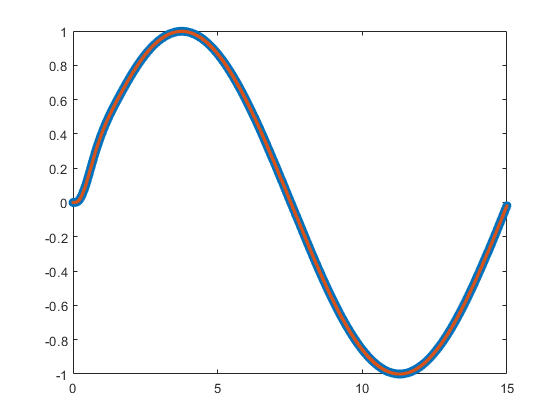

% dt = out.STATES(:,1);
% x = out.STATES(:,2);
% 
% 
% new_dt = 0:0.005:15;
% new_x = interp1(dt,x,new_dt)
% 
% 
% figure
% plot(dt,x,'o',new_dt,new_x,'-');
% legend('Samples','Cubic Interpolation');

% Defining new variables
dt = out.STATES_SAMPLED(:,1)'; 
x = out.STATES_SAMPLED(:,2)';
y = out.STATES_SAMPLED(:,3)';
z = out.STATES_SAMPLED(:,4)';

% Extracting unique values from the arrays in the same order
[dt,IA,IC] = unique(dt,'stable');
[x,IA,IC] = unique(x,'stable');
[y,IA,IC] = unique(y,'stable');
[z,IA,IC] = unique(z,'stable');

% The sample time similar to "NMPCdesired"
dt_new = 0:0.005:15;

% Generate i.e. interpolate new values
x_new = interp1(dt,x(1:3301),dt_new,'cubic');
y_new = interp1(dt,y(1:3301),dt_new,'cubic');
z_new = interp1(dt,z(1:3301),dt_new,'cubic');

% Verify  by plots
figure
plot(dt,x(1:3301),'o',dt_new,x_new,':.');

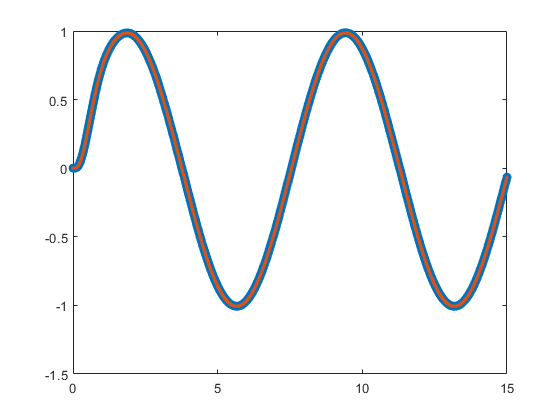

plot(dt,y(1:3301),'o',dt_new,y_new,':.');

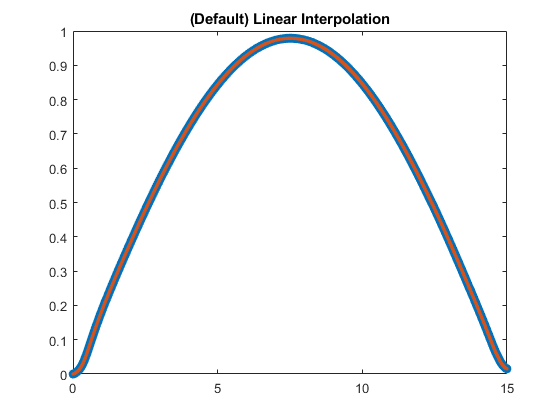

plot(dt,z(1:3301),'o',dt_new,z_new,':.');
xlim([0 15]);
title('(Default) Linear Interpolation');


dt = out.STATES_SAMPLED(:,1)'; 
dt_new = 0:0.005:15;
[dt,IA,IC] = unique(dt,'stable');
dt_size = size(dt);

new_out = [dt_new'];
for i=2:14 % x,y,z, .... 
var = out.STATES_SAMPLED(:,i)';   
[var,IA,IC] = unique(var,'stable');
var_new = interp1(dt,var(1:dt_size(1,2)),dt_new,'cubic');
new_out = [new_out var_new'];    
end

out.STATES = new_out; 

## PLOTS

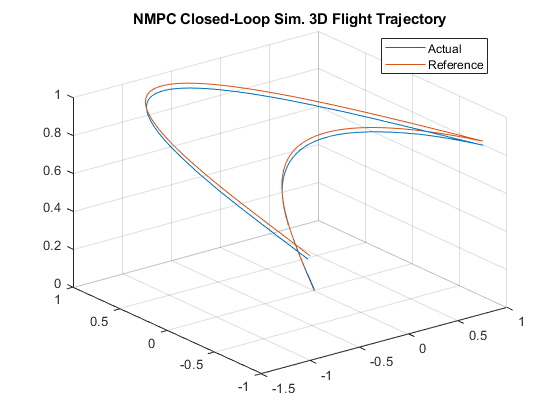

if EXPORT
     
else
% % RMSE
% summ = 0;
% % fnb = 2388;
% % fn = 221;
% % cf = round((223 - fn)*(fnb/fn));
% % fdev = (fnb-cf)/fn;
% fn = 2600
% 
% for ii=1:fn 
%     
% % sz = size(out.STATES(round(fdev*(ii-1)+1):round(fdev*ii),2));
% % % x mean
% % x_m = sum(out.STATES(round(fdev*(ii-1)+1):round(fdev*ii),2))/sz(1,1);
% % % y mean
% % y_m = sum(out.STATES(round(fdev*(ii-1)+1):round(fdev*ii),3))/sz(1,1);
% % % z mean
% % z_m = sum(out.STATES(round(fdev*(ii-1)+1):round(fdev*ii),4))/sz(1,1);
% % % v mean
% % v_m = [x_m y_m z_m]';
% 
% summ = summ + norm((out.STATES(ii,2:4)'- figure8_new.NMPCdesired.all(ii,2:4)'),2)^2;
%     
% end
% 
% %RMSE = sqrt(summ/fn)
% 
% ref = NMPCdesired.all; 
% actual = out.STATES;
% min_int_ref = 0;
% min_int_actual = 0;
% min_int_ref_save = [];
% min_int_actual_save = [];
% 
% 
% for i=1:3020
% minn = 100;    
% for ii=1:3020
% 
% compare = ref(i,1) - actual(ii,1);
% 
% if abs(compare)<= minn
% minn = abs(compare);
% min_int_ref = i;
% min_int_actual = ii;
% end    
% 
% 
% end
% min_int_ref_save = [min_int_ref_save min_int_ref];
% min_int_actual_save = [min_int_actual_save min_int_actual];
% end   
% 
% summ = 0;
% fn = 3020;
% for ii=1:fn
%     
% summ = summ + norm((out.STATES(min_int_actual_save(ii),2:4)'- NMPCdesired.all(min_int_ref_save(ii),2:4)'),2)^2;    
% end
% RMSE = sqrt(summ/fn)
%     
fn = 2500;  
figure('Name','NMPC Closed-Loop Sim. 3D Flight Trajectory')    
plot3(out.STATES(1:fn,2),out.STATES(1:fn,3),out.STATES(1:fn,4))
hold on 
plot3(NMPCdesired.all(1:fn,2),NMPCdesired.all(1:fn,3),NMPCdesired.all(1:fn,4))
legend([ 'Actual'],...
        [ 'Reference'],...
        'Location','Best');
title('NMPC Closed-Loop Sim. 3D Flight Trajectory')
grid on
hold off
end 

EXPORT TXT FILES 

% dlmwrite('ref.txt', NMPCdesired.all, 'delimiter', '\t');
fid = fopen('ref.txt', 'w');

for row = 1:size(NMPCdesired.all, 1)
    for col = 1:size(NMPCdesired.all, 2)
        fprintf(fid, '%s\t', NMPCdesired.all(row, col));
    end
    fprintf(fid, '\n');
end

fclose(fid);

fid = fopen('mesure.txt', 'w');

for row = 1:size(out.STATES, 1)
    for col = 1:size(out.STATES, 2)
        fprintf(fid, '%s\t', out.STATES(row, col));
    end
    fprintf(fid, '\n');
end

fclose(fid);